# mtRK Test

In this notebook, we're testing an implementation of masked quantile tensor randomized Kaczmarz (mQTRK).

Note: script requires the file mtRK_new.m 

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 4;
n = 6;
m = 20;
beta = (m-1)/(m*p); %proportion of corrupted entries in B
num_corrupt = floor(beta*m*p*n);% number of corruptions 
size_corrupt= 100; % size of corruptions 
num_its = 10000; % number of iterations

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);
B = tprod(A,X_true);

Now, let's test the implementation of tRK.

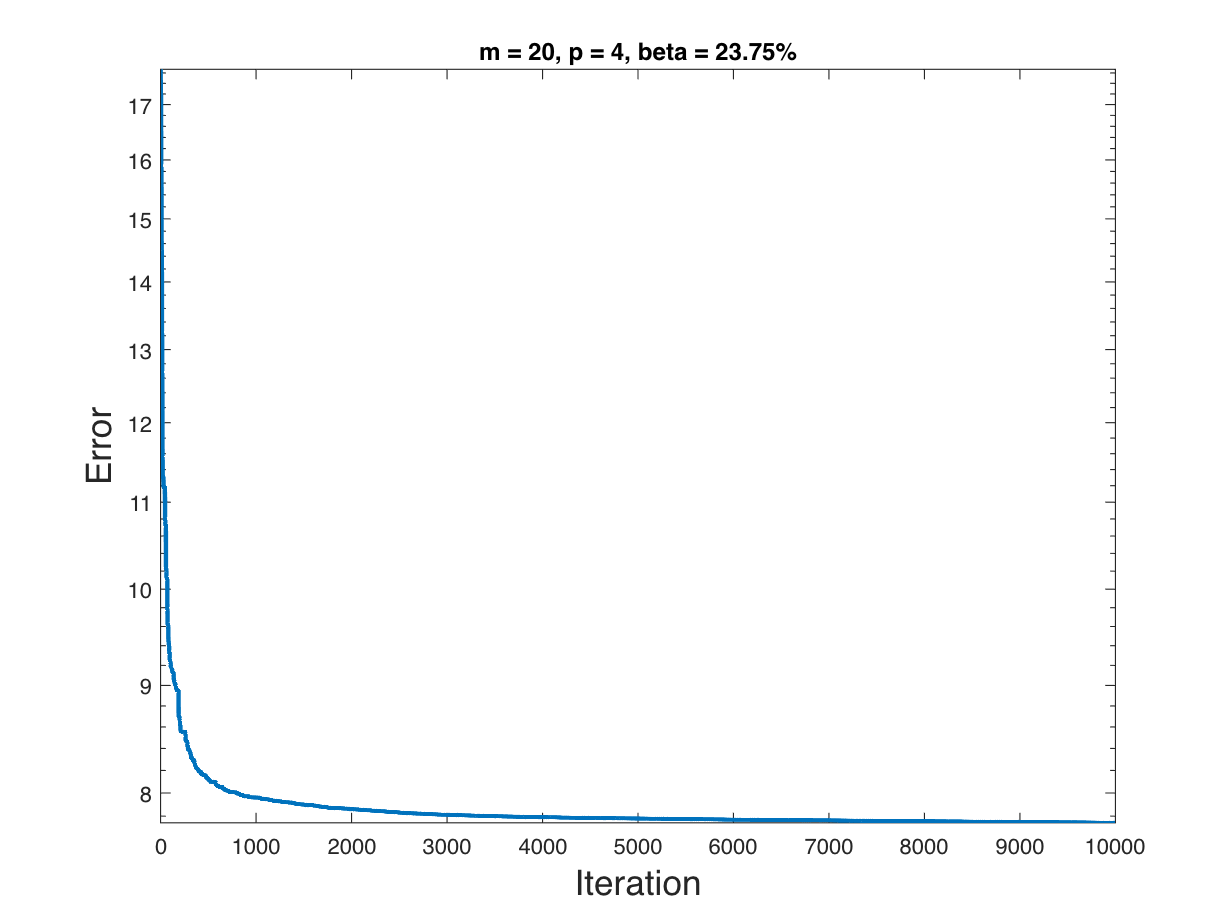

dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);

[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt; %original
end 
q = 1 - num_corrupt/(size(B,1)*size(B,2)*size(B,3)); %proportion of non-corrupted entries
[~,its] = mtRK_new(A,B,randn(l,p,n),num_its, q);

%record errors
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];
end

%plot errors vs iterations
semilogy(errs,'Linewidth',2)
title("m = " + m + ", p = " + p + ", beta = " + beta*100 + "%")
xlabel ('Iteration', FontSize=16)
ylabel('Error', FontSize=16)
xlim([0,num_its])

%axis([0 num_its 0 15])
